clear all;
close all;

clock_freq = 1e8;
limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 18, 20, 24, 28, 35, 45, 60, 75, 100, 125, 150, 175, 200];
time = limits.*(1e6/clock_freq);

model = "basys";

## TERO-4-PUF

prefix = "tero_4";

average_uniformities_tero_4 = zeros(1, length(limits));
average_reliabilities_tero_4 = zeros(1, length(limits));

data = readmatrix(model+"_"+prefix+'_raw_'+string(limits(1))+'.csv');
[size_sample_tero_4, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_raw_'+string(limits(i))+'.csv');
    [~, ~, ~, average_uniformities_tero_4(i), average_reliabilities_tero_4(i), ~, ~] = intra_device_analysis_fn(data);
end

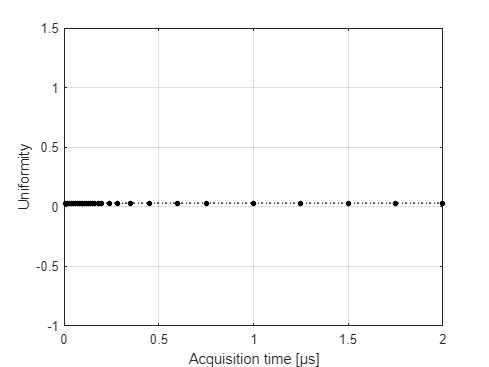


fig_tero_4_uniformities = figure;
p = plot(time, average_uniformities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Uniformity");
grid on;

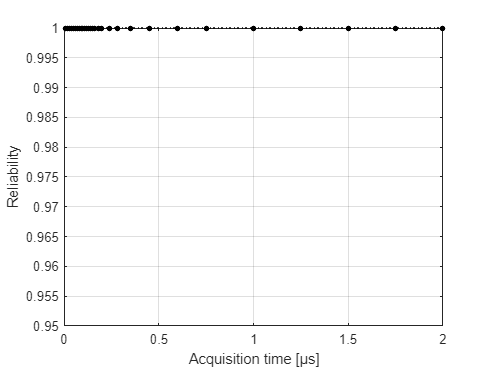


fig_tero_4_reliabilities = figure;
p = plot(time, average_reliabilities_tero_4./100, ':.');
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Reliability");
ylim([0.95 1]);
grid on;

## TERO-8-PUF

prefix = "tero_8";

average_uniformities_tero_8 = zeros(1, length(limits));
std_uniformities_tero_8 = zeros(1, length(limits));
average_reliabilities_tero_8 = zeros(1, length(limits));
std_reliabilities_tero_8 = zeros(1, length(limits));

data = readmatrix(model+"_"+prefix+'_raw_'+string(limits(1))+'.csv');
[size_sample_tero_8, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_"+prefix+'_raw_'+string(limits(i))+'.csv');
    [~, ~, ~, average_uniformities_tero_8(i), average_reliabilities_tero_8(i), ~, ~, std_uniformities_tero_8(i), std_reliabilities_tero_8(i)] = intra_device_analysis_fn(data);
end

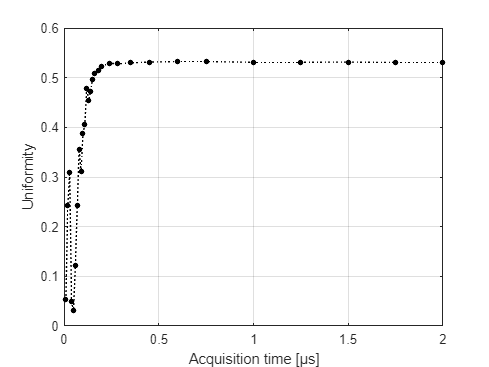

fig_tero_8_uniformities = figure;
p = plot(time, average_uniformities_tero_8./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Uniformity");
grid on;

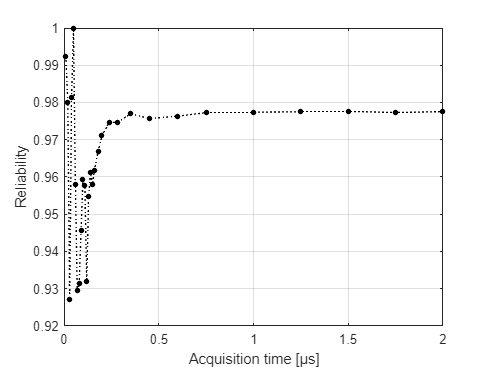


fig_tero_8_reliabilities = figure;
p = plot(time, average_reliabilities_tero_8./100, ':.');
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Reliability");
grid on;

## TERO-4 vs TERO-8

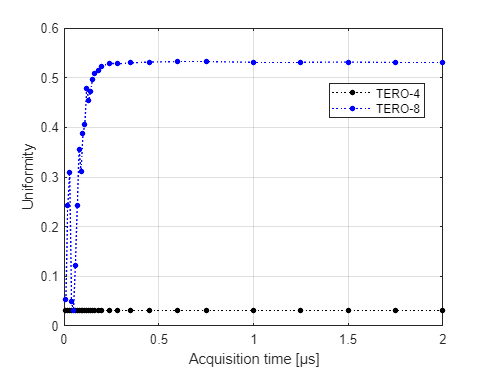

fig_tero_all_uniformities = figure;
p = plot(time, average_uniformities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
p = plot(time, average_uniformities_tero_8./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Uniformity");
grid on;
legend("TERO-4","TERO-8");

legend("Position", [0.65966,0.67238,0.2243,0.10748])

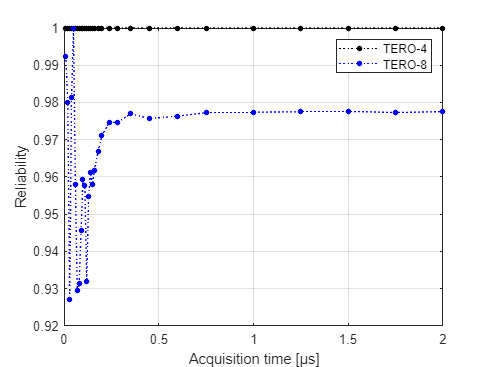


fig_tero_all_reliabilities = figure;
p = plot(time, average_reliabilities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
p = plot(time, average_reliabilities_tero_8./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Reliability");
ylim([0.92 1]);
grid on;
legend("TERO-4","TERO-8");

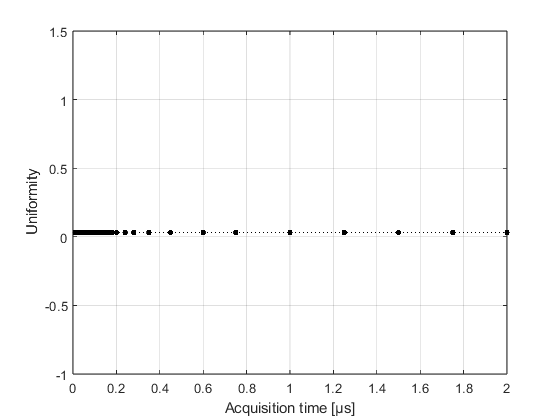

saveas(fig_tero_4_uniformities, "tero_4_intra_uniformity.png");

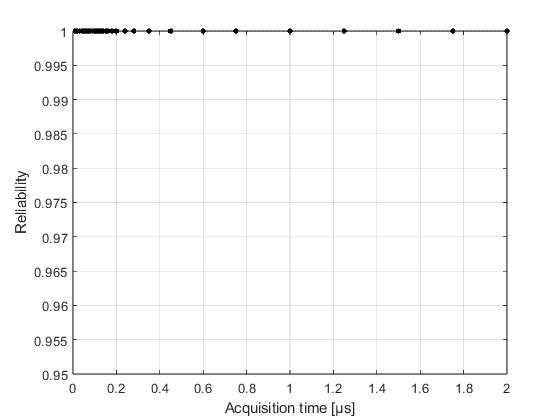

saveas(fig_tero_4_reliabilities, "tero_4_intra_reliability.png");

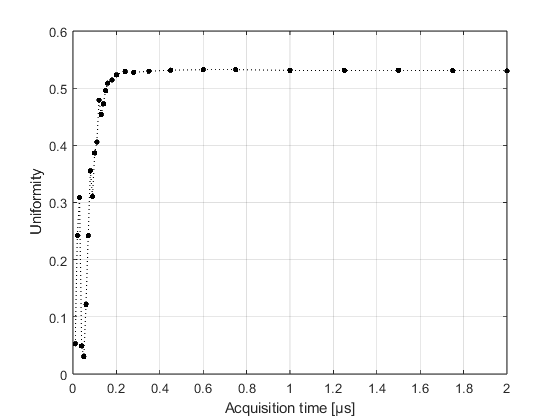

saveas(fig_tero_8_uniformities, "tero_8_intra_uniformity.png");

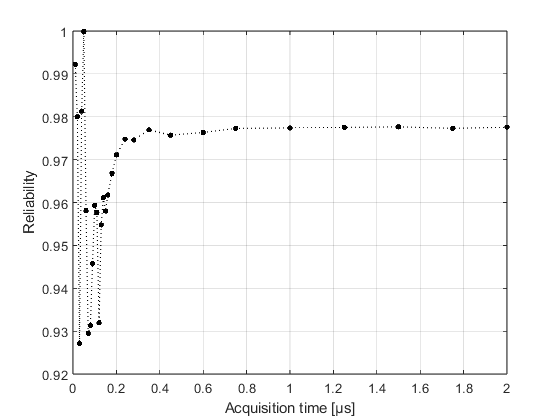

saveas(fig_tero_8_reliabilities, "tero_8_intra_reliability.png");

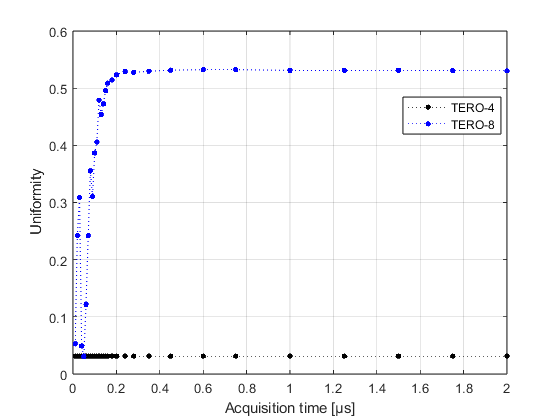

saveas(fig_tero_all_uniformities, "all_intra_uniformity.png");

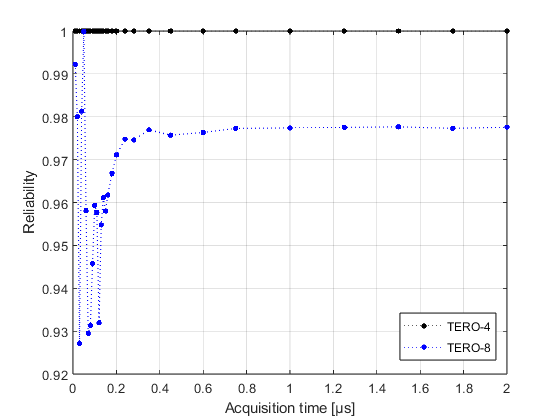

saveas(fig_tero_all_reliabilities, "all_intra_reliability.png");

## UNLOCKED

## TERO-4-PUF

prefix = "tero_4";

unlocked_average_uniformities_tero_4 = zeros(1, length(limits));
unlocked_average_reliabilities_tero_4 = zeros(1, length(limits));

data = readmatrix(model+"_unlocked_"+prefix+'_raw_'+string(limits(1))+'.csv');
[size_sample_tero_4, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_unlocked_"+prefix+'_raw_'+string(limits(i))+'.csv');
    [~, ~, ~, unlocked_average_uniformities_tero_4(i), unlocked_average_reliabilities_tero_4(i), ~, ~] = intra_device_analysis_fn(data);
end

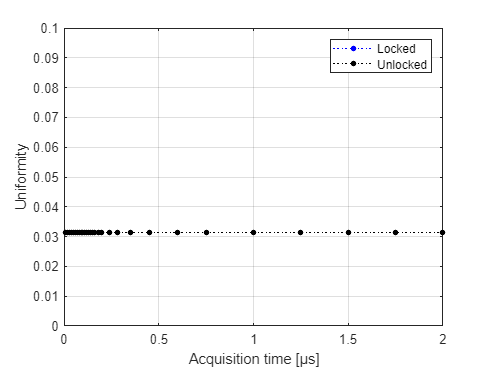


fig_unlocked_tero_4_uniformities = figure;
p = plot(time, average_uniformities_tero_4./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
p = plot(time, unlocked_average_uniformities_tero_4./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Uniformity");
ylim([0 0.1]);
grid on;
legend("Locked","Unlocked")

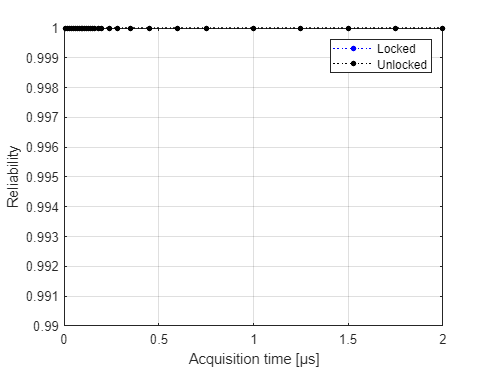


fig_unlocked_tero_4_reliabilities = figure;
p = plot(time, average_reliabilities_tero_4./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
p = plot(time, unlocked_average_reliabilities_tero_4./100, ':.');
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Reliability");
ylim([0.99 1]);
grid on;
legend("Locked","Unlocked")

## TERO-8-PUF

prefix = "tero_8";

unlocked_average_uniformities_tero_8 = zeros(1, length(limits));
unlocked_average_reliabilities_tero_8 = zeros(1, length(limits));

data = readmatrix(model+"_unlocked_"+prefix+'_raw_'+string(limits(1))+'.csv');
[size_sample_tero_8, size_response] = size(data);

for i=1:length(limits)
    data = readmatrix(model+"_unlocked_"+prefix+'_raw_'+string(limits(i))+'.csv');
    [~, ~, ~, unlocked_average_uniformities_tero_8(i), unlocked_average_reliabilities_tero_8(i), ~, ~, ~, ~] = intra_device_analysis_fn(data);
end

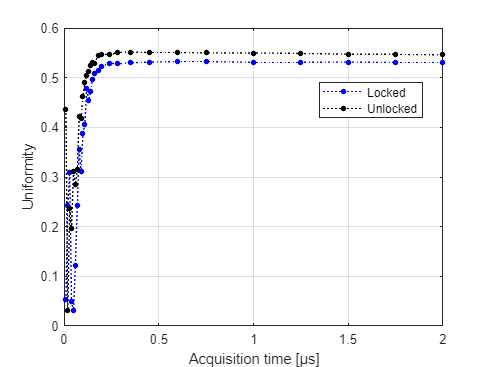

fig_unlocked_tero_8_uniformities = figure;
p = plot(time, average_uniformities_tero_8./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
p = plot(time, unlocked_average_uniformities_tero_8./100, ':.');hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Uniformity");
grid on;
legend("Locked","Unlocked")
legend("Position", [0.63957,0.67333,0.23832,0.11037])

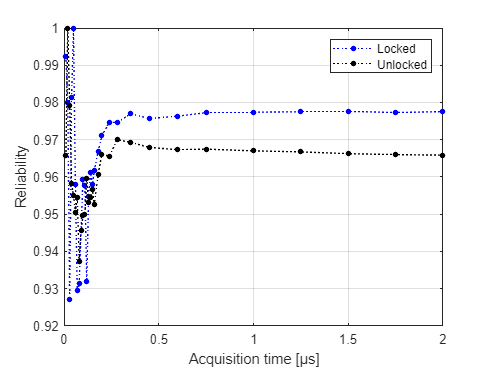


fig_unlocked_tero_8_reliabilities = figure;

p = plot(time, average_reliabilities_tero_8./100, ':.');hold on;
p.Color = 'blue';
p.MarkerFaceColor = 'blue';
p.MarkerSize = 12;
p = plot(time, unlocked_average_reliabilities_tero_8./100, ':.');
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
xlabel("Acquisition time [µs]");
ylabel("Reliability");
grid on;
legend("Locked","Unlocked")

saveas(fig_unlocked_tero_4_uniformities, "unlocked_tero_4_intra_uniformity.png");

saveas(fig_unlocked_tero_4_reliabilities, "unlocked_tero_4_intra_reliability.png");

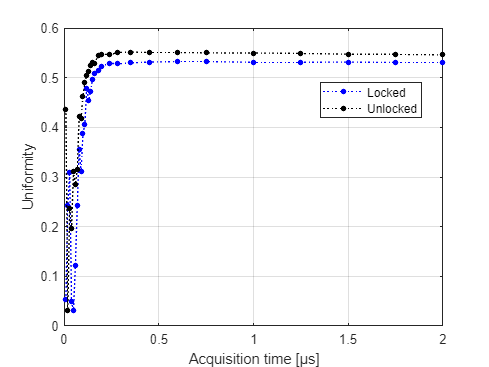

saveas(fig_unlocked_tero_8_uniformities, "unlocked_tero_8_intra_uniformity.png");

saveas(fig_unlocked_tero_8_reliabilities, "unlocked_tero_8_intra_reliability.png");